## Generate artificial data

clear all;

x = -4:0.05:4;
y = -4:0.05:4;

rng(123456);

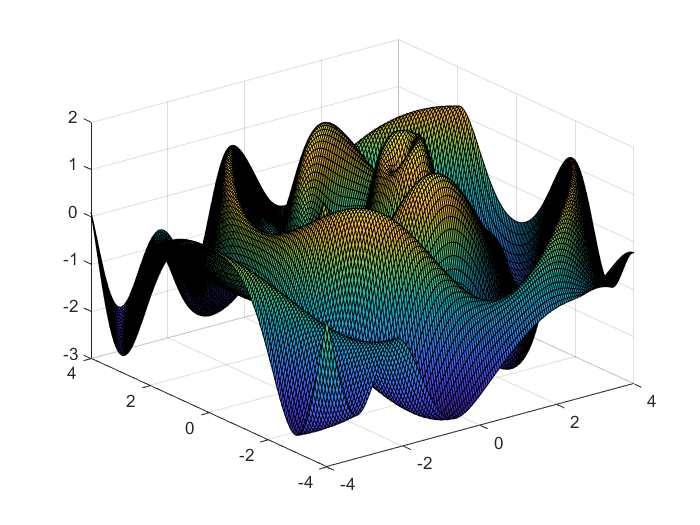

figure;
[X, Y] = meshgrid(x, y);
fkk = 2; % frequency of test function
freq=2*fkk; fk=1;
f1 = @(x,y) sin(freq*sqrt((x-fk).^2+y.^2));%./(freq*sqrt((x-fk).^2+y.^2));
freq=1*fkk; fk=-1;
f2 = @(x,y) -sin(freq*sqrt((x-fk).^2+y.^2));%./(freq*sqrt((x-fk).^2+y.^2));
freq = 0.1*fkk;
f3 = @(x,y) -sin(freq*sqrt(x.^2+y.^2));
ff = @(x,y) f1(x,y)+f2(x,y)+f3(x,y);
Z = ff(X, Y);
%Z = peaks(X, Y);
surf(X, Y, Z);

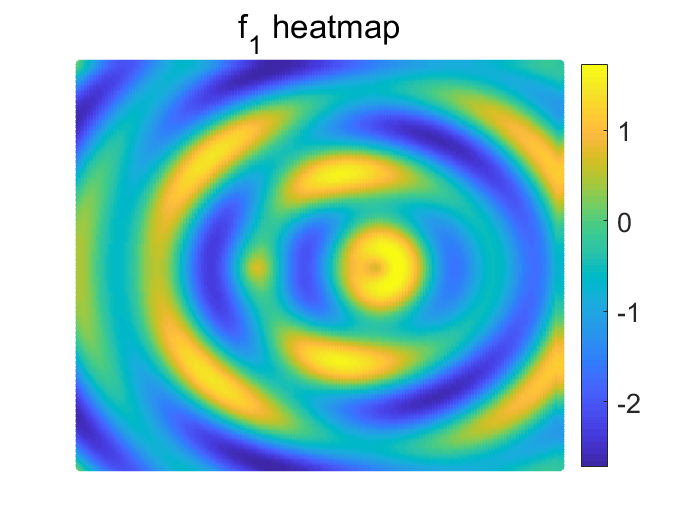

figure;
scatter(X(:), Y(:), [], Z(:), "filled");
axis off
set(gca,'fontsize', 18);
title('f_1 heatmap')
colorbar;

xnorm = 1; ynorm = 1; % whether use normalization
yns = 0.1; % noise scale

n = 1e4; % size of training data
ttcs = 300;
ttm = round(n / (ttcs/2));

% represent_ratio = 5;
% dcs = 300; % size of the communication set
% mn = round(n / dcs); % mn is the number of experts (normal)
% m = round(n / (dcs*represent_ratio)); % m is the number of experts (sparse representative)
% lamds = 0:0.5:3.0;

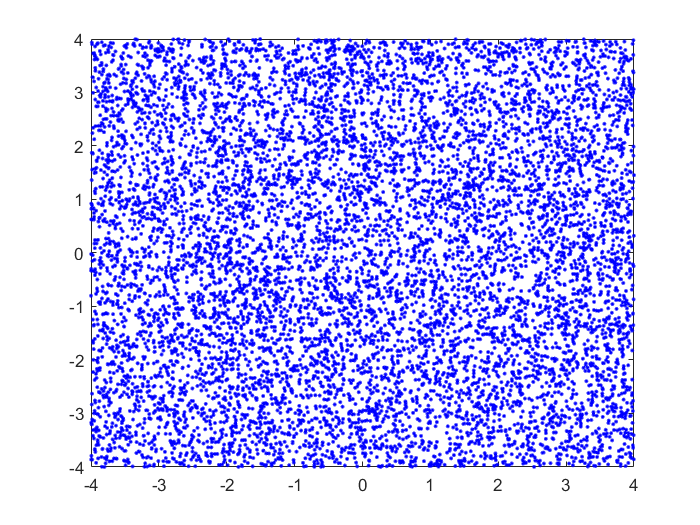

testsize = 2000; % size of test data
valsize = 1000;
induce_step = 100;

% training input
ori_all_trainxs = 8*(rand(n, 1)-0.5);
ori_all_trainys = 8*(rand(n, 1)-0.5);

figure;
plot(ori_all_trainxs, ori_all_trainys, 'b.');

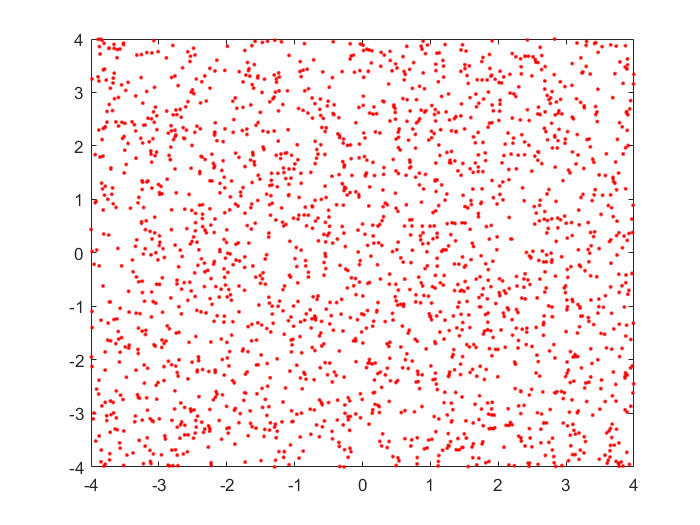


% test input
ori_testxs = 8*(rand(testsize, 1)-0.5);
ori_testys = 8*(rand(testsize, 1)-0.5);

% validation input
ori_valxs = 8*(rand(valsize, 1)-0.5);
ori_valys = 8*(rand(valsize, 1)-0.5);

figure;
plot(ori_testxs, ori_testys, 'r.');


% ininput normalization
if xnorm == 1
    norm_xmean = mean(ori_all_trainxs);
    norm_xstd = std(ori_all_trainxs);
    all_trainxs = (ori_all_trainxs - norm_xmean) / norm_xstd;
    norm_ymean = mean(ori_all_trainys);
    norm_ystd = std(ori_all_trainys);
    all_trainys = (ori_all_trainys - norm_ymean) / norm_ystd;
    
    testxs = (ori_testxs - norm_xmean) / norm_xstd;
    testys = (ori_testys - norm_ymean) / norm_ystd;
    
    valxs = (ori_valxs - norm_xmean) / norm_xstd;
    valys = (ori_valys - norm_ymean) / norm_ystd;
else
    all_trainxs = ori_all_trainxs;
    all_trainys = ori_all_trainys;
    testxs = ori_testxs;
    testys = ori_testys;    
    valxs = ori_valxs;
    valys = ori_valys;    
end

% training output
ln = length(all_trainxs);
xvec = zeros(ln, 2); ori_xvec = zeros(ln, 2);
for i = 1:ln
    xvec(i, :) = [all_trainxs(i), all_trainys(i)];
    ori_xvec(i, :) = [ori_all_trainxs(i), ori_all_trainys(i)];
end
ori_yvec = ff(ori_all_trainxs, ori_all_trainys) + yns*randn(ln, 1);

% test output
ln = length(testxs);
xvec_test = zeros(ln, 2); ori_xvec_test = zeros(ln, 2);
for i = 1:ln
    xvec_test(i, :) = [testxs(i), testys(i)];
    ori_xvec_test(i, :) = [ori_testxs(i), ori_testys(i)];
end
ori_yvec_test = ff(ori_testxs, ori_testys) + yns*randn(ln, 1);

% validation output
ln = length(valxs);
xvec_val = zeros(ln, 2); ori_xvec_val = zeros(ln, 2);
for i = 1:ln
    xvec_val(i, :) = [valxs(i), valys(i)];
    ori_xvec_val(i, :) = [ori_valxs(i), ori_valys(i)];
end
ori_yvec_val = ff(ori_valxs, ori_valys) + yns*randn(ln, 1);

% output normalization
if ynorm == 1
    norm_fmean = mean(ori_yvec);
    norm_fstd = std(ori_yvec);
    all_trainxs = (ori_all_trainxs - norm_xmean) / norm_xstd;
    yvec = (ori_yvec - norm_fmean) / norm_fstd;
    yvec_test = (ori_yvec_test - norm_fmean) / norm_fstd;
    yvec_val = (ori_yvec_val - norm_fmean) / norm_fstd;
else
    yvec = ori_yvec;
    yvec_test = ori_yvec_test;
    yvec_val = ori_yvec_val;
end

store results

kti = 5; % average over kti runs
grls = 0.3:0.05:1.0; % percentage of remaining data to be test
grbcm0_smse_rec = zeros(kti, 1);
rbcm0_smse_rec = zeros(kti, 1);
bcm0_smse_rec = zeros(kti, 1);
gpoe0_smse_rec = zeros(kti, 1);
poe0_smse_rec = zeros(kti, 1);
vfe0_smse_rec = zeros(kti, 1);
spgp0_smse_rec = zeros(kti, 1);
grbcm0_msll_rec = zeros(kti, 1);
rbcm0_msll_rec = zeros(kti, 1);
bcm0_msll_rec = zeros(kti, 1);
gpoe0_msll_rec = zeros(kti, 1);
poe0_msll_rec = zeros(kti, 1);
vfe0_msll_rec = zeros(kti, 1);
spgp0_msll_rec = zeros(kti, 1);
grbcm_gr_smse = zeros(kti, length(grls));
grbcm_gr_msll = zeros(kti, length(grls));
grbcm2_gr_smse = zeros(kti, length(grls));
grbcm2_gr_msll = zeros(kti, length(grls));
grbcm2_spgp_gr_smse = zeros(kti, length(grls));
grbcm2_spgp_gr_msll = zeros(kti, length(grls));

## Experiment I: remove data from the training set

sf2 = 1 ; ell = 1 ; sn2 = 0.1 ; 
d = size(xvec,2);
opts.Xnorm = 'N' ; opts.Ynorm = 'N' ;
opts.Ms = ttm+1;
opts.ell = ell ; opts.sf2 = sf2 ; opts.sn2 = sn2 ;
opts.meanfunc = []; opts.covfunc = @covSEard; opts.likfunc = @likGauss; opts.inffunc = @infGaussLik ;

meanfunc = [];                    % empty: don't use a mean function
covfunc = opts.covfunc;              % Squared Exponental covariance function
likfunc = opts.likfunc;              % Gaussian likelihood
inffunc = opts.inffunc;
km_iters = 1e4;
opts.induce_step = induce_step ;

% hyp.cov = log([ones(d,1)*ell;sf2]); hyp.lik = log(sn2); hyp.mean = [];    
opts.numOptFC = 50 ;
opts.Ms = ttm+1;
opts.xvec = xvec;
opts.yvec = yvec;
opts.grbcm_baseline = 0;
opts.global_index = ones(n,1);
% opts.inffunc = @infGaussLik; opts.meanfunc = meanfunc; opts.likfunc = likfunc;
opts.covfunc = covfunc;
covfuncF = {@apxSparse, {opts.covfunc}, []};
opts.covfuncF = covfuncF;
opts.compute_hyp = 0;

% default partition
dcs_ecs_r = 0.5;
dcs = round(ttcs*dcs_ecs_r) % size of the communication set

dcs = 150

ecs = ttcs - dcs % size of other experts

ecs = 150

n_per = dcs ; % size of Dc
mn = round(n / ecs); % mn is the number of experts (normal)
Indics = randperm(n) ;
I_com = Indics(1:n_per) ; % randomly select communication set
[idx, C] = kmeans(xvec, mn,'MaxIter',km_iters);    

Baselines of VFE and SPGP.

% hyp.cov = log([ones(d,1)*ell;sf2]); hyp.lik = log(sn2); hyp.mean = [];    
opts.numOptFC = 30 ;
opts.Ms = mn+1;
opts.xvec = xvec;
opts.yvec = yvec;
opts.induce_size = dcs;
opts.grbcm_baseline = 0;
opts.global_index = ones(n,1);
opts.I_com = I_com;
% opts.inffunc = @infGaussLik; opts.meanfunc = meanfunc; opts.likfunc = likfunc;
opts.covfunc = covfunc;
covfuncF = {@apxSparse, {opts.covfunc}, xvec(I_com,:)};
opts.covfuncF = covfuncF;
opts.compute_hyp = 0;

g_opts = opts;
g_opts.compute_hyp = 1;
g_opts.grbcm_baseline = 1;
g_opts.global_index = ones(n,1);
g_models = aggregation_train_GRBCM_VS_apx(xvec,yvec,idx,g_opts); 

Optimizing hyps in training...
Linesearch      0;  Value 5.162781e+03
Linesearch      1;  Value 2.449878e+03
Linesearch      2;  Value -1.331980e+03
Linesearch      3;  Value -5.249277e+03
Linesearch      4;  Value -5.962682e+03
Linesearch      5;  Value -6.032907e+03
Linesearch      6;  Value -6.069304e+03
Linesearch      7;  Value -6.274396e+03
Linesearch      8;  Value -6.315859e+03
Linesearch      9;  Value -6.320591e+03
Linesearch     10;  Value -6.322875e+03
Linesearch     11;  Value -6.323489e+03
Linesearch     12;  Value -6.324257e+03
Linesearch     13;  Value -6.325137e+03
Linesearch     14;  Value -6.325151e+03
Linesearch     15;  Value -6.325154e+03
Linesearch     16;  Value -6.325154e+03
Linesearch     17;  Value -6.325155e+03
Linesearch     18;  Value -6.325155e+03
Linesearch     19;  Value -6.325155e+03
Linesearch     20;  Value -6.325155e+03
Linesearch     21;  Value -6.325155e+03
Linesearch     22;  Value -6.325155e+03
Linesearch     23;  Value -6.325155e+03
Linesearch 

opts.hyp = g_models{1}.hyp;
g_opts.hyp = g_models{1}.hyp;
[tmu,ts2, ~] =  aggregation_predict(xvec_test,g_models,'GRBCM', 1, g_opts);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end

[grbcmMSE,grbcmSMSE,grbcmMSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.8f, MSLL %6.8f\r\n', 'GRBCM', n_per, grbcmMSE,grbcmSMSE,grbcmMSLL);

GRBCM (Dc size 150): MSE 0.01179634, SMSE 0.01238287, MSLL -2.04868360



g_opts.compute_hyp = 0;

When testing baseline, VFE and SPGP use all partition budget (ttcs = dcs + ecs).

I_com2 = Indics(1:ttcs) ; % randomly select communication set

% % VFE Baseline
vfe_opts = opts;
vfe_opts.induce_type = 'VFE_opt';
xu = xvec(I_com2, :);
inffunc = @(varargin) infGaussLik(varargin{:}, struct('s', 0.0));
vfe_hyp = opts.hyp;
vfe_hyp.xu = xu;
[vfe_hyp, tmp_nlzs] = minimize(vfe_hyp,@sp_gp,-vfe_opts.induce_step,inffunc,meanfunc,covfuncF,likfunc,xvec,yvec);

Function evaluation      0;  Value 6.697854e+02
Function evaluation     10;  Value -8.441569e+02
Function evaluation     13;  Value -2.343632e+03
Function evaluation     14;  Value -4.484990e+03
Function evaluation     15;  Value -4.940360e+03
Function evaluation     18;  Value -5.556287e+03
Function evaluation     19;  Value -6.084505e+03
Function evaluation     21;  Value -6.381782e+03
Function evaluation     23;  Value -6.572633e+03
Function evaluation     24;  Value -6.739983e+03
Function evaluation     27;  Value -6.819390e+03
Function evaluation     28;  Value -6.895779e+03
Function evaluation     30;  Value -6.933462e+03
Function evaluation     32;  Value -6.952915e+03
Function evaluation     35;  Value -6.980646e+03
Function evaluation     37;  Value -6.998711e+03
Function evaluation     39;  Value -7.014689e+03
Function evaluation     41;  Value -7.025193e+03
Function evaluation     43;  Value -7.032373e+03
Function evaluation     45;  Value -7.038789e+03
Function evaluation  

vfe_opts.hyp = opts.hyp;
vfe_opts.xu = vfe_hyp.xu;
vfe_opts.inffunc = @infGaussLik; vfe_opts.meanfunc = meanfunc; vfe_opts.covfuncF = covfuncF; vfe_opts.likfunc = likfunc;
vfe_opts.covfunc = covfunc;
[tmu, ts2] = gp(vfe_hyp, @infGaussLik, meanfunc, covfuncF, likfunc, xvec, yvec, xvec_test);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end
[vfeMSE,vfeSMSE,vfeMSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.8f, MSLL %6.8f\r\n', 'VFE baseline', n_per, vfeMSE,vfeSMSE,vfeMSLL);

VFE baseline (Dc size 150): MSE 0.01095326, SMSE 0.01149786, MSLL -2.22928219


% vfe0_smse_rec(ki) = vfeSMSE; vfe0_msll_rec(ki) = vfeMSLL;
[yu, su] = gp(vfe_hyp, @infGaussLik, meanfunc, covfuncF, likfunc, xvec, yvec, vfe_opts.xu);
vfe_opts.yu = yu; vfe_opts.su = su; 

sp_opts = opts;
sp_opts.induce_size = ttcs;
sp_opts.induce_type = 'SPGP_opt';
hyp_init(1:d,1) = -2*opts.hyp.cov(1:d);
hyp_init(d+1,1) = 2*opts.hyp.cov(d+1);
hyp_init(d+2,1) = 2*opts.hyp.lik;

xu = xvec(I_com2, :);
w_init = [reshape(xu,sp_opts.induce_size*d,1);hyp_init];
[w,tmp_nlzs] = minimize(w_init,'spgp_lik_nohyp',-sp_opts.induce_step,yvec,xvec,sp_opts.induce_size);

Function evaluation      0;  Value -6.615935e+03
Function evaluation      8;  Value -6.773176e+03
Function evaluation     10;  Value -7.129234e+03
Function evaluation     12;  Value -7.258895e+03
Function evaluation     16;  Value -7.359168e+03
Function evaluation     18;  Value -7.453648e+03
Function evaluation     19;  Value -7.520448e+03
Function evaluation     21;  Value -7.564845e+03
Function evaluation     23;  Value -7.587883e+03
Function evaluation     26;  Value -7.617321e+03
Function evaluation     29;  Value -7.624374e+03
Function evaluation     31;  Value -7.638049e+03
Function evaluation     33;  Value -7.645932e+03
Function evaluation     35;  Value -7.658067e+03
Function evaluation     37;  Value -7.662863e+03
Function evaluation     39;  Value -7.663976e+03
Function evaluation     42;  Value -7.669416e+03
Function evaluation     46;  Value -7.670158e+03
Function evaluation     50;  Value -7.680442e+03
Function evaluation     53;  Value -7.681455e+03
Function evaluation 

xb = reshape(w(1:sp_opts.induce_size*d,1),sp_opts.induce_size,d);
sp_opts.xu = xb;
sp_opts.sp_hyp = w(sp_opts.induce_size*d+1:end,1);
sp_opts.hyp = opts.hyp;
[tmu,ts2] = spgp_pred(sp_opts.yvec,sp_opts.xvec,sp_opts.xu,xvec_test,sp_opts.sp_hyp);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end
[spgpMSE,spgpSMSE,spgpMSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.8f, MSLL %6.8f\r\n', 'SPSG baseline', n_per, spgpMSE,spgpSMSE,spgpMSLL);

SPSG baseline (Dc size 150): MSE 0.01103506, SMSE 0.01158373, MSLL -2.21967138


% spgp0_smse_rec(ki) = spgpSMSE; spgp0_msll_rec(ki) = spgpMSLL;
[yu,su] = spgp_pred(sp_opts.yvec,sp_opts.xvec,sp_opts.xu,sp_opts.xu,sp_opts.sp_hyp);
sp_opts.yu = yu; sp_opts.su = su;

Average over 5 runs.

==============1================

Optimizing hyps in training...
Linesearch      0;  Value 5.348556e+03
Linesearch      1;  Value 3.198132e+03
Linesearch      2;  Value 6.486279e-01
Linesearch      3;  Value -5.161712e+03
Linesearch      4;  Value -5.967865e+03
Linesearch      5;  Value -5.994283e+03
Linesearch      6;  Value -6.046665e+03
Linesearch      7;  Value -6.275880e+03
Linesearch      8;  Value -6.311265e+03
Linesearch      9;  Value -6.319052e+03
Linesearch     10;  Value -6.319813e+03
Linesearch     11;  Value -6.320328e+03
Linesearch     12;  Value -6.320551e+03
Linesearch     13;  Value -6.321073e+03
Linesearch     14;  Value -6.321179e+03
Linesearch     15;  Value -6.321180e+03
Linesearch     16;  Value -6.321180e+03
Linesearch     17;  Value -6.321180e+03
Linesearch     18;  Value -6.321180e+03
Linesearch     19;  Value -6.321180e+03
Linesearch     20;  Value -6.321180e+03
Linesearch     21;  Value -6.321180e+03
Linesearch     22;  Value -6.321180e+03
Linesearch     23;  Value -6.321180e+03
Linesearch  

GRBCM (Dc size 150): MSE 0.01167919, SMSE 0.01225989, MSLL -2.04398353


Function evaluation      0;  Value 7.950124e+04
Function evaluation     17;  Value 5.742614e+04
Function evaluation     20;  Value 4.121167e+04
Function evaluation     22;  Value 3.136348e+04
Function evaluation     24;  Value 2.626477e+04
Function evaluation     26;  Value 2.337475e+04
Function evaluation     28;  Value 2.148508e+04
Function evaluation     30;  Value 2.026360e+04
Function evaluation     32;  Value 1.930558e+04
Function evaluation     33;  Value 1.835089e+04
Function evaluation     34;  Value 1.745123e+04
Function evaluation     36;  Value 1.697089e+04
Function evaluation     37;  Value 1.648788e+04
Function evaluation     39;  Value 1.613724e+04
Function evaluation     41;  Value 1.583193e+04
Function evaluation     43;  Value 1.560947e+04
Function evaluation     45;  Value 1.541403e+04
Function evaluation     47;  Value 1.523824e+04
Function evaluation     49;  Value 1.508769e+04
Function evaluation     51;  Value 1.491889e+04
Function evaluation     53;  Value 1.479

VFE (Dc size 150): MSE 0.01354364, SMSE 0.01421704, MSLL -1.84901647


Function evaluation      0;  Value -5.884254e+02
Function evaluation     10;  Value -1.421366e+03
Function evaluation     11;  Value -1.734470e+03
Function evaluation     14;  Value -2.179429e+03
Function evaluation     15;  Value -2.627418e+03
Function evaluation     17;  Value -2.984641e+03
Function evaluation     19;  Value -3.250924e+03
Function evaluation     21;  Value -3.415378e+03
Function evaluation     22;  Value -3.583756e+03
Function evaluation     24;  Value -3.707973e+03
Function evaluation     26;  Value -3.805608e+03
Function evaluation     28;  Value -3.891737e+03
Function evaluation     30;  Value -3.938965e+03
Function evaluation     31;  Value -3.989162e+03
Function evaluation     33;  Value -4.022996e+03
Function evaluation     35;  Value -4.049214e+03
Function evaluation     37;  Value -4.066934e+03
Function evaluation     39;  Value -4.078528e+03
Function evaluation     41;  Value -4.093458e+03
Function evaluation     43;  Value -4.106530e+03
Function evaluation 

SPSG (Dc size 150): MSE 0.02679972, SMSE 0.02813221, MSLL -1.83800889


GRBCM (VFE) (Dc size 150): MSE 0.01096672, SMSE 0.01151199, MSLL -2.20573773


GRBCM (SPGP) (Dc size 150): MSE 0.01107424, SMSE 0.01162485, MSLL -2.19211926


RBCM (Dc size 150): MSE 0.01163737, SMSE 0.0122, MSLL -1.5545


BCM (Dc size 150): MSE 0.01210811, SMSE 0.0127, MSLL -2.0883


PoE (Dc size 150): MSE 0.07492287, SMSE 0.0786, MSLL 4.0461


GPoE (Dc size 150): MSE 0.01159644, SMSE 0.0122, MSLL -1.5402


processing distance: 100/10000
processing distance: 200/10000
processing distance: 300/10000
processing distance: 400/10000
processing distance: 500/10000
processing distance: 600/10000
processing distance: 700/10000
processing distance: 800/10000
processing distance: 900/10000
processing distance: 1000/10000
processing distance: 1100/10000
processing distance: 1200/10000
processing distance: 1300/10000
processing distance: 1400/10000
processing distance: 1500/10000
processing distance: 1600/10000
processing distance: 1700/10000
processing distance: 1800/10000
processing distance: 1900/10000
processing distance: 2000/10000
processing distance: 2100/10000
processing distance: 2200/10000
processing distance: 2300/10000
processing distance: 2400/10000
processing distance: 2500/10000
processing distance: 2600/10000
processing distance: 2700/10000
processing distance: 2800/10000
processing distance: 2900/10000
processing distance: 3000/10000
processing distance: 3100/10000
processing distan

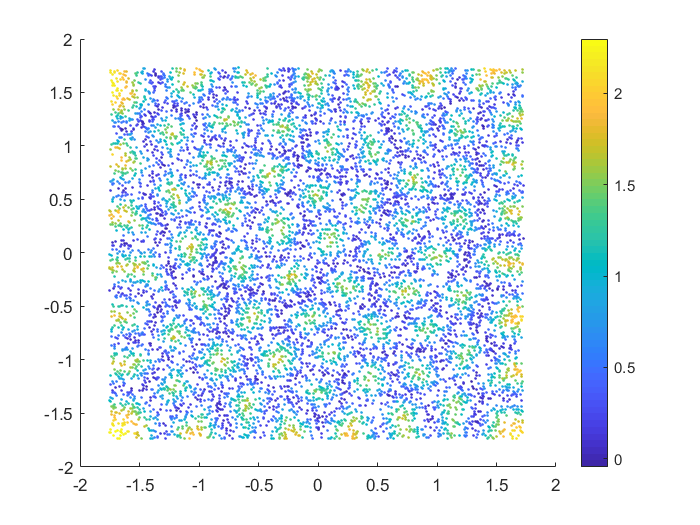

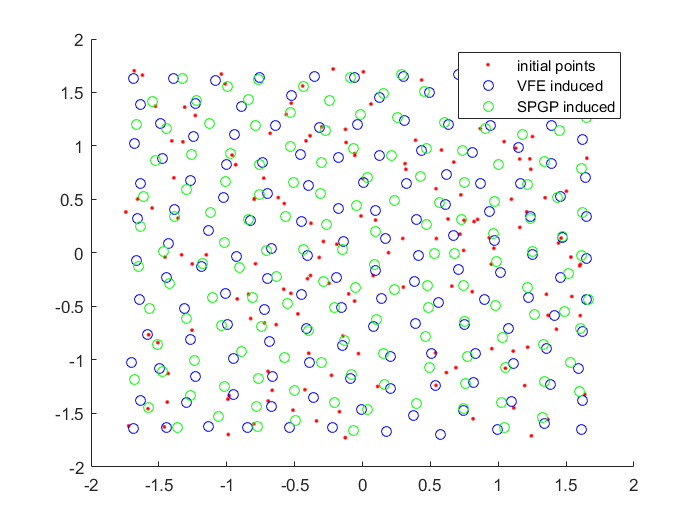

kj = 1

gr = 0.3000

GRBCM (Dc size 150): MSE 0.01714609, SMSE 0.0180, MSLL -1.9993


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01294670, SMSE 0.0136, MSLL -2.0994


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01283995, SMSE 0.0135, MSLL -2.0967


kj = 2

gr = 0.3500

GRBCM (Dc size 150): MSE 0.01535923, SMSE 0.0161, MSLL -2.0414


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01244671, SMSE 0.0131, MSLL -2.1289


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01296413, SMSE 0.0136, MSLL -2.1101


kj = 3

gr = 0.4000

GRBCM (Dc size 150): MSE 0.01490274, SMSE 0.0156, MSLL -2.0509


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01251024, SMSE 0.0131, MSLL -2.1418


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01289494, SMSE 0.0135, MSLL -2.1176


kj = 4

gr = 0.4500

GRBCM (Dc size 150): MSE 0.01385486, SMSE 0.0145, MSLL -2.0812


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01232231, SMSE 0.0129, MSLL -2.1556


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01262081, SMSE 0.0132, MSLL -2.1304


kj = 5

gr = 0.5000

GRBCM (Dc size 150): MSE 0.01339933, SMSE 0.0141, MSLL -2.0888


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01197107, SMSE 0.0126, MSLL -2.1741


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01217578, SMSE 0.0128, MSLL -2.1519


kj = 6

gr = 0.5500

GRBCM (Dc size 150): MSE 0.01283660, SMSE 0.0135, MSLL -2.1000


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01180346, SMSE 0.0124, MSLL -2.1839


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01184557, SMSE 0.0124, MSLL -2.1668


kj = 7

gr = 0.6000

GRBCM (Dc size 150): MSE 0.01264798, SMSE 0.0133, MSLL -2.0982


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01175515, SMSE 0.0123, MSLL -2.1860


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01168298, SMSE 0.0123, MSLL -2.1756


kj = 8

gr = 0.6500

GRBCM (Dc size 150): MSE 0.01237319, SMSE 0.0130, MSLL -2.1021


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01167596, SMSE 0.0123, MSLL -2.1894


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01160196, SMSE 0.0122, MSLL -2.1807


kj = 9

gr = 0.7000

GRBCM (Dc size 150): MSE 0.01219244, SMSE 0.0128, MSLL -2.0979


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01149606, SMSE 0.0121, MSLL -2.1960


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01147325, SMSE 0.0120, MSLL -2.1864


kj = 10

gr = 0.7500

GRBCM (Dc size 150): MSE 0.01202299, SMSE 0.0126, MSLL -2.0939


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01145886, SMSE 0.0120, MSLL -2.1949


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01139427, SMSE 0.0120, MSLL -2.1891


kj = 11

gr = 0.8000

GRBCM (Dc size 150): MSE 0.01190146, SMSE 0.0125, MSLL -2.0865


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01133002, SMSE 0.0119, MSLL -2.1994


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01131969, SMSE 0.0119, MSLL -2.1904


kj = 12

gr = 0.8500

GRBCM (Dc size 150): MSE 0.01187640, SMSE 0.0125, MSLL -2.0724


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01120582, SMSE 0.0118, MSLL -2.2035


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01125901, SMSE 0.0118, MSLL -2.1915


kj = 13

gr = 0.9000

GRBCM (Dc size 150): MSE 0.01185711, SMSE 0.0124, MSLL -2.0565


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01113010, SMSE 0.0117, MSLL -2.2037


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01120412, SMSE 0.0118, MSLL -2.1912


kj = 14

gr = 0.9500

GRBCM (Dc size 150): MSE 0.01182736, SMSE 0.0124, MSLL -2.0434


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01115135, SMSE 0.0117, MSLL -2.1983


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01122711, SMSE 0.0118, MSLL -2.1863


kj = 15

gr = 1

GRBCM (Dc size 150): MSE 0.01167919, SMSE 0.0123, MSLL -2.0440


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01096672, SMSE 0.0115, MSLL -2.2057


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01107424, SMSE 0.0116, MSLL -2.1921


==============2================

Optimizing hyps in training...
Linesearch      0;  Value 5.089840e+03
Linesearch      1;  Value 2.731101e+03
Linesearch      2;  Value -6.480282e+02
Linesearch      3;  Value -5.181594e+03
Linesearch      4;  Value -5.955388e+03
Linesearch      5;  Value -5.998779e+03
Linesearch      6;  Value -6.282407e+03
Linesearch      7;  Value -6.321093e+03
Linesearch      8;  Value -6.333914e+03
Linesearch      9;  Value -6.338392e+03
Linesearch     10;  Value -6.339216e+03
Linesearch     11;  Value -6.340207e+03
Linesearch     12;  Value -6.341290e+03
Linesearch     13;  Value -6.341544e+03
Linesearch     14;  Value -6.341586e+03
Linesearch     15;  Value -6.341587e+03
Linesearch     16;  Value -6.341587e+03
Linesearch     17;  Value -6.341587e+03
Linesearch     18;  Value -6.341587e+03
Linesearch     19;  Value -6.341587e+03
Linesearch     20;  Value -6.341587e+03


GRBCM (Dc size 150): MSE 0.01160220, SMSE 0.01217907, MSLL -2.01256376


Function evaluation      0;  Value 1.040156e+05
Function evaluation     13;  Value 8.451655e+04
Function evaluation     14;  Value 5.898573e+04
Function evaluation     16;  Value 5.073139e+04
Function evaluation     20;  Value 4.445325e+04
Function evaluation     23;  Value 3.596614e+04
Function evaluation     25;  Value 3.152799e+04
Function evaluation     27;  Value 2.838439e+04
Function evaluation     29;  Value 2.541922e+04
Function evaluation     31;  Value 2.310987e+04
Function evaluation     33;  Value 2.121239e+04
Function evaluation     35;  Value 2.007394e+04
Function evaluation     37;  Value 1.924869e+04
Function evaluation     39;  Value 1.870391e+04
Function evaluation     41;  Value 1.835022e+04
Function evaluation     43;  Value 1.792558e+04
Function evaluation     44;  Value 1.753509e+04
Function evaluation     46;  Value 1.733291e+04
Function evaluation     48;  Value 1.700943e+04
Function evaluation     50;  Value 1.676965e+04
Function evaluation     52;  Value 1.647

VFE (Dc size 150): MSE 0.01401075, SMSE 0.01470737, MSLL -1.86040455


Function evaluation      0;  Value 5.863321e+02
Function evaluation     10;  Value -2.146545e+02
Function evaluation     11;  Value -8.272364e+02
Function evaluation     13;  Value -1.343785e+03
Function evaluation     14;  Value -2.153561e+03
Function evaluation     17;  Value -2.460914e+03
Function evaluation     18;  Value -2.801010e+03
Function evaluation     20;  Value -3.000167e+03
Function evaluation     21;  Value -3.225526e+03
Function evaluation     23;  Value -3.327432e+03
Function evaluation     25;  Value -3.476395e+03
Function evaluation     27;  Value -3.584656e+03
Function evaluation     29;  Value -3.667870e+03
Function evaluation     31;  Value -3.741339e+03
Function evaluation     32;  Value -3.812040e+03
Function evaluation     33;  Value -3.888835e+03
Function evaluation     35;  Value -3.930045e+03
Function evaluation     37;  Value -3.983780e+03
Function evaluation     39;  Value -4.006408e+03
Function evaluation     41;  Value -4.039461e+03
Function evaluation  

SPSG (Dc size 150): MSE 0.02038188, SMSE 0.02139528, MSLL -1.84900875


GRBCM (VFE) (Dc size 150): MSE 0.01113766, SMSE 0.01169143, MSLL -2.19969480


GRBCM (SPGP) (Dc size 150): MSE 0.01122891, SMSE 0.01178722, MSLL -2.18577418


RBCM (Dc size 150): MSE 0.01178301, SMSE 0.0124, MSLL -1.5069


BCM (Dc size 150): MSE 0.01240724, SMSE 0.0130, MSLL -2.0547


PoE (Dc size 150): MSE 0.08296068, SMSE 0.0871, MSLL 4.8601


GPoE (Dc size 150): MSE 0.01200084, SMSE 0.0126, MSLL -1.4487


processing distance: 100/10000
processing distance: 200/10000
processing distance: 300/10000
processing distance: 400/10000
processing distance: 500/10000
processing distance: 600/10000
processing distance: 700/10000
processing distance: 800/10000
processing distance: 900/10000
processing distance: 1000/10000
processing distance: 1100/10000
processing distance: 1200/10000
processing distance: 1300/10000
processing distance: 1400/10000
processing distance: 1500/10000
processing distance: 1600/10000
processing distance: 1700/10000
processing distance: 1800/10000
processing distance: 1900/10000
processing distance: 2000/10000
processing distance: 2100/10000
processing distance: 2200/10000
processing distance: 2300/10000
processing distance: 2400/10000
processing distance: 2500/10000
processing distance: 2600/10000
processing distance: 2700/10000
processing distance: 2800/10000
processing distance: 2900/10000
processing distance: 3000/10000
processing distance: 3100/10000
processing distan

kj = 1

gr = 0.3000

GRBCM (Dc size 150): MSE 0.01645326, SMSE 0.0173, MSLL -2.0176


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01252005, SMSE 0.0131, MSLL -2.1154


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01289758, SMSE 0.0135, MSLL -2.1079


kj = 2

gr = 0.3500

GRBCM (Dc size 150): MSE 0.01471285, SMSE 0.0154, MSLL -2.0607


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01223477, SMSE 0.0128, MSLL -2.1397


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01242399, SMSE 0.0130, MSLL -2.1333


kj = 3

gr = 0.4000

GRBCM (Dc size 150): MSE 0.01390630, SMSE 0.0146, MSLL -2.0813


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01203128, SMSE 0.0126, MSLL -2.1561


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01219785, SMSE 0.0128, MSLL -2.1487


kj = 4

gr = 0.4500

GRBCM (Dc size 150): MSE 0.01366430, SMSE 0.0143, MSLL -2.0827


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01195445, SMSE 0.0125, MSLL -2.1684


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01205253, SMSE 0.0127, MSLL -2.1605


kj = 5

gr = 0.5000

GRBCM (Dc size 150): MSE 0.01320293, SMSE 0.0139, MSLL -2.0867


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01189683, SMSE 0.0125, MSLL -2.1757


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01185056, SMSE 0.0124, MSLL -2.1712


kj = 6

gr = 0.5500

GRBCM (Dc size 150): MSE 0.01267610, SMSE 0.0133, MSLL -2.0989


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01172411, SMSE 0.0123, MSLL -2.1858


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01159844, SMSE 0.0122, MSLL -2.1845


kj = 7

gr = 0.6000

GRBCM (Dc size 150): MSE 0.01230181, SMSE 0.0129, MSLL -2.1075


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01157335, SMSE 0.0121, MSLL -2.1937


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01142521, SMSE 0.0120, MSLL -2.1947


kj = 8

gr = 0.6500

GRBCM (Dc size 150): MSE 0.01204366, SMSE 0.0126, MSLL -2.1073


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01125783, SMSE 0.0118, MSLL -2.2080


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01122048, SMSE 0.0118, MSLL -2.2042


kj = 9

gr = 0.7000

GRBCM (Dc size 150): MSE 0.01185176, SMSE 0.0124, MSLL -2.0996


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01130194, SMSE 0.0119, MSLL -2.2052


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01125249, SMSE 0.0118, MSLL -2.2014


kj = 10

gr = 0.7500

GRBCM (Dc size 150): MSE 0.01180675, SMSE 0.0124, MSLL -2.0850


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01124613, SMSE 0.0118, MSLL -2.2059


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01124539, SMSE 0.0118, MSLL -2.2005


kj = 11

gr = 0.8000

GRBCM (Dc size 150): MSE 0.01178812, SMSE 0.0124, MSLL -2.0645


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01120920, SMSE 0.0118, MSLL -2.2054


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01125543, SMSE 0.0118, MSLL -2.1978


kj = 12

gr = 0.8500

GRBCM (Dc size 150): MSE 0.01175981, SMSE 0.0123, MSLL -2.0461


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01121910, SMSE 0.0118, MSLL -2.2032


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01125280, SMSE 0.0118, MSLL -2.1961


kj = 13

gr = 0.9000

GRBCM (Dc size 150): MSE 0.01179525, SMSE 0.0124, MSLL -2.0241


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01125634, SMSE 0.0118, MSLL -2.1983


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01132701, SMSE 0.0119, MSLL -2.1873


kj = 14

gr = 0.9500

GRBCM (Dc size 150): MSE 0.01167367, SMSE 0.0123, MSLL -2.0151


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01120543, SMSE 0.0118, MSLL -2.1993


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01127511, SMSE 0.0118, MSLL -2.1867


kj = 15

gr = 1

GRBCM (Dc size 150): MSE 0.01160220, SMSE 0.0122, MSLL -2.0126


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01113766, SMSE 0.0117, MSLL -2.1997


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01122891, SMSE 0.0118, MSLL -2.1858


==============3================

Optimizing hyps in training...
Linesearch      0;  Value 5.512977e+03
Linesearch      1;  Value 3.683710e+03
Linesearch      2;  Value -5.187491e+01
Linesearch      3;  Value -4.961891e+03
Linesearch      4;  Value -5.942128e+03
Linesearch      5;  Value -6.029953e+03
Linesearch      6;  Value -6.067542e+03
Linesearch      7;  Value -6.143129e+03
Linesearch      8;  Value -6.327389e+03
Linesearch      9;  Value -6.345919e+03
Linesearch     10;  Value -6.354405e+03
Linesearch     11;  Value -6.355023e+03
Linesearch     12;  Value -6.355161e+03
Linesearch     13;  Value -6.355242e+03
Linesearch     14;  Value -6.355376e+03
Linesearch     15;  Value -6.355377e+03
Linesearch     16;  Value -6.355378e+03
Linesearch     17;  Value -6.355378e+03
Linesearch     18;  Value -6.355378e+03
Linesearch     19;  Value -6.355378e+03
Linesearch     20;  Value -6.355378e+03
Linesearch     21;  Value -6.355378e+03
Linesearch     22;  Value -6.355378e+03
Linesearch     23;  Value -6.355378e+03
Linesearch 

GRBCM (Dc size 150): MSE 0.01135319, SMSE 0.01191768, MSLL -2.03362075


Function evaluation      0;  Value 1.346522e+05
Function evaluation     14;  Value 9.687493e+04
Function evaluation     16;  Value 6.821785e+04
Function evaluation     19;  Value 5.241793e+04
Function evaluation     21;  Value 4.307679e+04
Function evaluation     23;  Value 3.602983e+04
Function evaluation     25;  Value 3.232844e+04
Function evaluation     27;  Value 3.002530e+04
Function evaluation     28;  Value 2.750688e+04
Function evaluation     30;  Value 2.651008e+04
Function evaluation     31;  Value 2.546837e+04
Function evaluation     32;  Value 2.441634e+04
Function evaluation     33;  Value 2.347748e+04
Function evaluation     35;  Value 2.207025e+04
Function evaluation     37;  Value 2.136670e+04
Function evaluation     39;  Value 1.983043e+04
Function evaluation     41;  Value 1.873354e+04
Function evaluation     43;  Value 1.806335e+04
Function evaluation     45;  Value 1.751504e+04
Function evaluation     47;  Value 1.723077e+04
Function evaluation     49;  Value 1.683

VFE (Dc size 150): MSE 0.01442134, SMSE 0.01513838, MSLL -1.84897726


Function evaluation      0;  Value 9.255962e+02
Function evaluation     11;  Value -4.274436e+02
Function evaluation     13;  Value -1.016861e+03
Function evaluation     14;  Value -1.554216e+03
Function evaluation     17;  Value -1.915739e+03
Function evaluation     18;  Value -2.268970e+03
Function evaluation     20;  Value -2.573743e+03
Function evaluation     22;  Value -2.815394e+03
Function evaluation     23;  Value -3.091806e+03
Function evaluation     25;  Value -3.240468e+03
Function evaluation     26;  Value -3.382498e+03
Function evaluation     27;  Value -3.520071e+03
Function evaluation     29;  Value -3.581907e+03
Function evaluation     30;  Value -3.647042e+03
Function evaluation     31;  Value -3.711008e+03
Function evaluation     33;  Value -3.764368e+03
Function evaluation     34;  Value -3.819982e+03
Function evaluation     36;  Value -3.856357e+03
Function evaluation     38;  Value -3.876767e+03
Function evaluation     39;  Value -3.898228e+03
Function evaluation  

SPSG (Dc size 150): MSE 0.02426854, SMSE 0.02547518, MSLL -1.83483730


GRBCM (VFE) (Dc size 150): MSE 0.01101956, SMSE 0.01156746, MSLL -2.19469860


GRBCM (SPGP) (Dc size 150): MSE 0.01110380, SMSE 0.01165589, MSLL -2.18275888


RBCM (Dc size 150): MSE 0.01131031, SMSE 0.0119, MSLL -1.6064


BCM (Dc size 150): MSE 0.01165530, SMSE 0.0122, MSLL -2.1163


PoE (Dc size 150): MSE 0.08241726, SMSE 0.0865, MSLL 4.8160


GPoE (Dc size 150): MSE 0.01146815, SMSE 0.0120, MSLL -1.5590


processing distance: 100/10000
processing distance: 200/10000
processing distance: 300/10000
processing distance: 400/10000
processing distance: 500/10000
processing distance: 600/10000
processing distance: 700/10000
processing distance: 800/10000
processing distance: 900/10000
processing distance: 1000/10000
processing distance: 1100/10000
processing distance: 1200/10000
processing distance: 1300/10000
processing distance: 1400/10000
processing distance: 1500/10000
processing distance: 1600/10000
processing distance: 1700/10000
processing distance: 1800/10000
processing distance: 1900/10000
processing distance: 2000/10000
processing distance: 2100/10000
processing distance: 2200/10000
processing distance: 2300/10000
processing distance: 2400/10000
processing distance: 2500/10000
processing distance: 2600/10000
processing distance: 2700/10000
processing distance: 2800/10000
processing distance: 2900/10000
processing distance: 3000/10000
processing distance: 3100/10000
processing distan

kj = 1

gr = 0.3000

GRBCM (Dc size 150): MSE 0.01742213, SMSE 0.0183, MSLL -1.9959


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01275115, SMSE 0.0134, MSLL -2.1069


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01336865, SMSE 0.0140, MSLL -2.0899


kj = 2

gr = 0.3500

GRBCM (Dc size 150): MSE 0.01594033, SMSE 0.0167, MSLL -2.0313


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01252040, SMSE 0.0131, MSLL -2.1300


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01264260, SMSE 0.0133, MSLL -2.1169


kj = 3

gr = 0.4000

GRBCM (Dc size 150): MSE 0.01492227, SMSE 0.0157, MSLL -2.0522


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01240532, SMSE 0.0130, MSLL -2.1456


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01213751, SMSE 0.0127, MSLL -2.1408


kj = 4

gr = 0.4500

GRBCM (Dc size 150): MSE 0.01428392, SMSE 0.0150, MSLL -2.0696


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01217578, SMSE 0.0128, MSLL -2.1628


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01201004, SMSE 0.0126, MSLL -2.1532


kj = 5

gr = 0.5000

GRBCM (Dc size 150): MSE 0.01394172, SMSE 0.0146, MSLL -2.0686


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01192043, SMSE 0.0125, MSLL -2.1774


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01189215, SMSE 0.0125, MSLL -2.1610


kj = 6

gr = 0.5500

GRBCM (Dc size 150): MSE 0.01310587, SMSE 0.0138, MSLL -2.0886


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01165004, SMSE 0.0122, MSLL -2.1899


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01159234, SMSE 0.0122, MSLL -2.1763


kj = 7

gr = 0.6000

GRBCM (Dc size 150): MSE 0.01292458, SMSE 0.0136, MSLL -2.0837


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01171318, SMSE 0.0123, MSLL -2.1887


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01164824, SMSE 0.0122, MSLL -2.1763


kj = 8

gr = 0.6500

GRBCM (Dc size 150): MSE 0.01221348, SMSE 0.0128, MSLL -2.1006


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01136712, SMSE 0.0119, MSLL -2.2014


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01129683, SMSE 0.0119, MSLL -2.1904


kj = 9

gr = 0.7000

GRBCM (Dc size 150): MSE 0.01201326, SMSE 0.0126, MSLL -2.0896


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01126327, SMSE 0.0118, MSLL -2.2037


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01121564, SMSE 0.0118, MSLL -2.1917


kj = 10

gr = 0.7500

GRBCM (Dc size 150): MSE 0.01185099, SMSE 0.0124, MSLL -2.0771


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01118529, SMSE 0.0117, MSLL -2.2050


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01118858, SMSE 0.0117, MSLL -2.1925


kj = 11

gr = 0.8000

GRBCM (Dc size 150): MSE 0.01171271, SMSE 0.0123, MSLL -2.0714


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01123571, SMSE 0.0118, MSLL -2.1997


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01130293, SMSE 0.0119, MSLL -2.1848


kj = 12

gr = 0.8500

GRBCM (Dc size 150): MSE 0.01157505, SMSE 0.0122, MSLL -2.0652


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01113014, SMSE 0.0117, MSLL -2.2021


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01121482, SMSE 0.0118, MSLL -2.1855


kj = 13

gr = 0.9000

GRBCM (Dc size 150): MSE 0.01146600, SMSE 0.0120, MSLL -2.0572


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01106299, SMSE 0.0116, MSLL -2.2025


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01115164, SMSE 0.0117, MSLL -2.1873


kj = 14

gr = 0.9500

GRBCM (Dc size 150): MSE 0.01143823, SMSE 0.0120, MSLL -2.0385


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01105183, SMSE 0.0116, MSLL -2.1977


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01113274, SMSE 0.0117, MSLL -2.1844


kj = 15

gr = 1

GRBCM (Dc size 150): MSE 0.01135319, SMSE 0.0119, MSLL -2.0336


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01101956, SMSE 0.0116, MSLL -2.1947


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01110380, SMSE 0.0117, MSLL -2.1828


==============4================

Optimizing hyps in training...
Linesearch      0;  Value 5.682543e+03
Linesearch      1;  Value 3.921634e+03
Linesearch      2;  Value -1.043246e+02
Linesearch      3;  Value -4.960623e+03
Linesearch      4;  Value -5.957136e+03
Linesearch      5;  Value -6.029089e+03
Linesearch      6;  Value -6.057816e+03
Linesearch      7;  Value -6.113186e+03
Linesearch      8;  Value -6.304975e+03
Linesearch      9;  Value -6.316080e+03
Linesearch     10;  Value -6.320624e+03
Linesearch     11;  Value -6.320666e+03
Linesearch     12;  Value -6.320761e+03
Linesearch     13;  Value -6.320872e+03
Linesearch     14;  Value -6.320874e+03
Linesearch     15;  Value -6.320874e+03
Linesearch     16;  Value -6.320874e+03
Linesearch     17;  Value -6.320874e+03
Linesearch     18;  Value -6.320874e+03
Linesearch     19;  Value -6.320874e+03
Linesearch     20;  Value -6.320874e+03
Linesearch     21;  Value -6.320874e+03
Linesearch     22;  Value -6.320874e+03
Linesearch     23;  Value -6.320874e+03
Linesearch 

GRBCM (Dc size 150): MSE 0.01138631, SMSE 0.01195244, MSLL -2.05504159


Function evaluation      0;  Value 1.142490e+05
Function evaluation     12;  Value 1.113859e+05
Function evaluation     18;  Value 8.308851e+04
Function evaluation     20;  Value 5.792462e+04
Function evaluation     22;  Value 4.483625e+04
Function evaluation     25;  Value 3.914904e+04
Function evaluation     28;  Value 3.674652e+04
Function evaluation     30;  Value 3.169483e+04
Function evaluation     32;  Value 2.951373e+04
Function evaluation     34;  Value 2.627185e+04
Function evaluation     36;  Value 2.425903e+04
Function evaluation     38;  Value 2.260305e+04
Function evaluation     39;  Value 2.082516e+04
Function evaluation     41;  Value 1.954613e+04
Function evaluation     43;  Value 1.810372e+04
Function evaluation     45;  Value 1.708142e+04
Function evaluation     47;  Value 1.668554e+04
Function evaluation     48;  Value 1.633552e+04
Function evaluation     50;  Value 1.600707e+04
Function evaluation     52;  Value 1.563527e+04
Function evaluation     54;  Value 1.542

VFE (Dc size 150): MSE 0.01369428, SMSE 0.01437516, MSLL -1.85346631


Function evaluation      0;  Value 4.021312e+02
Function evaluation     12;  Value 1.728804e+01
Function evaluation     13;  Value -7.943800e+02
Function evaluation     14;  Value -1.202223e+03
Function evaluation     15;  Value -1.823664e+03
Function evaluation     17;  Value -1.967633e+03
Function evaluation     20;  Value -2.535348e+03
Function evaluation     23;  Value -2.865392e+03
Function evaluation     24;  Value -3.150033e+03
Function evaluation     26;  Value -3.349528e+03
Function evaluation     28;  Value -3.475206e+03
Function evaluation     29;  Value -3.597365e+03
Function evaluation     31;  Value -3.695670e+03
Function evaluation     33;  Value -3.750279e+03
Function evaluation     34;  Value -3.804038e+03
Function evaluation     36;  Value -3.841558e+03
Function evaluation     37;  Value -3.876939e+03
Function evaluation     39;  Value -3.909624e+03
Function evaluation     40;  Value -3.939343e+03
Function evaluation     42;  Value -3.963785e+03
Function evaluation   

SPSG (Dc size 150): MSE 0.02680336, SMSE 0.02813604, MSLL -1.83995275


GRBCM (VFE) (Dc size 150): MSE 0.01103467, SMSE 0.01158333, MSLL -2.20228332


GRBCM (SPGP) (Dc size 150): MSE 0.01120941, SMSE 0.01176675, MSLL -2.16484132


RBCM (Dc size 150): MSE 0.01134600, SMSE 0.0119, MSLL -1.5743


BCM (Dc size 150): MSE 0.01169775, SMSE 0.0123, MSLL -2.1059


PoE (Dc size 150): MSE 0.08296839, SMSE 0.0871, MSLL 4.7381


GPoE (Dc size 150): MSE 0.01151482, SMSE 0.0121, MSLL -1.5272


processing distance: 100/10000
processing distance: 200/10000
processing distance: 300/10000
processing distance: 400/10000
processing distance: 500/10000
processing distance: 600/10000
processing distance: 700/10000
processing distance: 800/10000
processing distance: 900/10000
processing distance: 1000/10000
processing distance: 1100/10000
processing distance: 1200/10000
processing distance: 1300/10000
processing distance: 1400/10000
processing distance: 1500/10000
processing distance: 1600/10000
processing distance: 1700/10000
processing distance: 1800/10000
processing distance: 1900/10000
processing distance: 2000/10000
processing distance: 2100/10000
processing distance: 2200/10000
processing distance: 2300/10000
processing distance: 2400/10000
processing distance: 2500/10000
processing distance: 2600/10000
processing distance: 2700/10000
processing distance: 2800/10000
processing distance: 2900/10000
processing distance: 3000/10000
processing distance: 3100/10000
processing distan

kj = 1

gr = 0.3000

GRBCM (Dc size 150): MSE 0.01595837, SMSE 0.0168, MSLL -2.0265


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01211736, SMSE 0.0127, MSLL -2.1230


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01256023, SMSE 0.0132, MSLL -2.1048


kj = 2

gr = 0.3500

GRBCM (Dc size 150): MSE 0.01548360, SMSE 0.0163, MSLL -2.0378


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01199388, SMSE 0.0126, MSLL -2.1450


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01335590, SMSE 0.0140, MSLL -2.0943


kj = 3

gr = 0.4000

GRBCM (Dc size 150): MSE 0.01460795, SMSE 0.0153, MSLL -2.0598


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01184564, SMSE 0.0124, MSLL -2.1644


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01253760, SMSE 0.0132, MSLL -2.1252


kj = 4

gr = 0.4500

GRBCM (Dc size 150): MSE 0.01407411, SMSE 0.0148, MSLL -2.0717


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01161265, SMSE 0.0122, MSLL -2.1811


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01232130, SMSE 0.0129, MSLL -2.1343


kj = 5

gr = 0.5000

GRBCM (Dc size 150): MSE 0.01305125, SMSE 0.0137, MSLL -2.1007


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01159146, SMSE 0.0122, MSLL -2.1877


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01196185, SMSE 0.0126, MSLL -2.1512


kj = 6

gr = 0.5500

GRBCM (Dc size 150): MSE 0.01273670, SMSE 0.0134, MSLL -2.1023


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01157749, SMSE 0.0122, MSLL -2.1930


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01206880, SMSE 0.0127, MSLL -2.1390


kj = 7

gr = 0.6000

GRBCM (Dc size 150): MSE 0.01244571, SMSE 0.0131, MSLL -2.0997


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01154565, SMSE 0.0121, MSLL -2.1964


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01202250, SMSE 0.0126, MSLL -2.1407


kj = 8

gr = 0.6500

GRBCM (Dc size 150): MSE 0.01198044, SMSE 0.0126, MSLL -2.1102


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01132503, SMSE 0.0119, MSLL -2.2053


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01170875, SMSE 0.0123, MSLL -2.1522


kj = 9

gr = 0.7000

GRBCM (Dc size 150): MSE 0.01172428, SMSE 0.0123, MSLL -2.1137


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01121936, SMSE 0.0118, MSLL -2.2097


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01147616, SMSE 0.0120, MSLL -2.1634


kj = 10

gr = 0.7500

GRBCM (Dc size 150): MSE 0.01163670, SMSE 0.0122, MSLL -2.1034


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01116597, SMSE 0.0117, MSLL -2.2116


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01144770, SMSE 0.0120, MSLL -2.1618


kj = 11

gr = 0.8000

GRBCM (Dc size 150): MSE 0.01153454, SMSE 0.0121, MSLL -2.0982


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01114944, SMSE 0.0117, MSLL -2.2116


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01137583, SMSE 0.0119, MSLL -2.1653


kj = 12

gr = 0.8500

GRBCM (Dc size 150): MSE 0.01141710, SMSE 0.0120, MSLL -2.0929


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01104408, SMSE 0.0116, MSLL -2.2129


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01119356, SMSE 0.0118, MSLL -2.1779


kj = 13

gr = 0.9000

GRBCM (Dc size 150): MSE 0.01143970, SMSE 0.0120, MSLL -2.0740


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01105871, SMSE 0.0116, MSLL -2.2094


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01128521, SMSE 0.0118, MSLL -2.1640


kj = 14

gr = 0.9500

GRBCM (Dc size 150): MSE 0.01144164, SMSE 0.0120, MSLL -2.0611


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01105742, SMSE 0.0116, MSLL -2.2047


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01125448, SMSE 0.0118, MSLL -2.1644


kj = 15

gr = 1

GRBCM (Dc size 150): MSE 0.01138631, SMSE 0.0120, MSLL -2.0550


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01103467, SMSE 0.0116, MSLL -2.2023


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01120941, SMSE 0.0118, MSLL -2.1648


==============5================

Optimizing hyps in training...
Linesearch      0;  Value 5.678914e+03
Linesearch      1;  Value 4.326059e+03
Linesearch      2;  Value 9.678355e+01
Linesearch      3;  Value -4.226635e+03
Linesearch      4;  Value -5.798305e+03
Linesearch      5;  Value -6.007995e+03
Linesearch      6;  Value -6.029221e+03
Linesearch      7;  Value -6.088565e+03
Linesearch      8;  Value -6.237039e+03
Linesearch      9;  Value -6.304053e+03
Linesearch     10;  Value -6.316978e+03
Linesearch     11;  Value -6.321609e+03
Linesearch     12;  Value -6.322706e+03
Linesearch     13;  Value -6.323990e+03
Linesearch     14;  Value -6.325219e+03
Linesearch     15;  Value -6.325285e+03
Linesearch     16;  Value -6.325319e+03
Linesearch     17;  Value -6.325322e+03
Linesearch     18;  Value -6.325324e+03
Linesearch     19;  Value -6.325326e+03
Linesearch     20;  Value -6.325328e+03
Linesearch     21;  Value -6.325329e+03
Linesearch     22;  Value -6.325329e+03
Linesearch     23;  Value -6.325329e+03
Linesearch  

GRBCM (Dc size 150): MSE 0.01156363, SMSE 0.01213859, MSLL -2.05963517


Function evaluation      0;  Value 1.050391e+05
Function evaluation     15;  Value 8.856876e+04
Function evaluation     17;  Value 7.018265e+04
Function evaluation     19;  Value 5.380945e+04
Function evaluation     21;  Value 4.100629e+04
Function evaluation     24;  Value 3.683781e+04
Function evaluation     25;  Value 3.285062e+04
Function evaluation     26;  Value 2.818606e+04
Function evaluation     28;  Value 2.509073e+04
Function evaluation     30;  Value 2.234363e+04
Function evaluation     32;  Value 2.119001e+04
Function evaluation     34;  Value 2.038796e+04
Function evaluation     35;  Value 1.942617e+04
Function evaluation     37;  Value 1.877418e+04
Function evaluation     38;  Value 1.806047e+04
Function evaluation     39;  Value 1.743878e+04
Function evaluation     41;  Value 1.705809e+04
Function evaluation     42;  Value 1.668191e+04
Function evaluation     44;  Value 1.637200e+04
Function evaluation     46;  Value 1.616339e+04
Function evaluation     47;  Value 1.594

VFE (Dc size 150): MSE 0.01375008, SMSE 0.01443375, MSLL -1.85202085


Function evaluation      0;  Value 1.265675e+03
Function evaluation     10;  Value -1.304765e+02
Function evaluation     11;  Value -4.295228e+02
Function evaluation     13;  Value -1.139805e+03
Function evaluation     15;  Value -1.621861e+03
Function evaluation     16;  Value -2.078991e+03
Function evaluation     18;  Value -2.461884e+03
Function evaluation     20;  Value -2.803806e+03
Function evaluation     22;  Value -3.033987e+03
Function evaluation     23;  Value -3.255860e+03
Function evaluation     25;  Value -3.446551e+03
Function evaluation     27;  Value -3.615087e+03
Function evaluation     29;  Value -3.704842e+03
Function evaluation     31;  Value -3.745494e+03
Function evaluation     33;  Value -3.802596e+03
Function evaluation     35;  Value -3.835498e+03
Function evaluation     37;  Value -3.873769e+03
Function evaluation     38;  Value -3.913906e+03
Function evaluation     40;  Value -3.962753e+03
Function evaluation     42;  Value -3.991531e+03
Function evaluation  

SPSG (Dc size 150): MSE 0.02511683, SMSE 0.02636565, MSLL -1.84206929


GRBCM (VFE) (Dc size 150): MSE 0.01105753, SMSE 0.01160732, MSLL -2.21164923


GRBCM (SPGP) (Dc size 150): MSE 0.01104832, SMSE 0.01159765, MSLL -2.18395599


RBCM (Dc size 150): MSE 0.01179357, SMSE 0.0124, MSLL -1.5002


BCM (Dc size 150): MSE 0.01231563, SMSE 0.0129, MSLL -2.0595


PoE (Dc size 150): MSE 0.07685495, SMSE 0.0807, MSLL 4.2245


GPoE (Dc size 150): MSE 0.01186660, SMSE 0.0125, MSLL -1.4664


processing distance: 100/10000
processing distance: 200/10000
processing distance: 300/10000
processing distance: 400/10000
processing distance: 500/10000
processing distance: 600/10000
processing distance: 700/10000
processing distance: 800/10000
processing distance: 900/10000
processing distance: 1000/10000
processing distance: 1100/10000
processing distance: 1200/10000
processing distance: 1300/10000
processing distance: 1400/10000
processing distance: 1500/10000
processing distance: 1600/10000
processing distance: 1700/10000
processing distance: 1800/10000
processing distance: 1900/10000
processing distance: 2000/10000
processing distance: 2100/10000
processing distance: 2200/10000
processing distance: 2300/10000
processing distance: 2400/10000
processing distance: 2500/10000
processing distance: 2600/10000
processing distance: 2700/10000
processing distance: 2800/10000
processing distance: 2900/10000
processing distance: 3000/10000
processing distance: 3100/10000
processing distan

kj = 1

gr = 0.3000

GRBCM (Dc size 150): MSE 0.01653127, SMSE 0.0174, MSLL -2.0217


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01236918, SMSE 0.0130, MSLL -2.1174


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01236400, SMSE 0.0130, MSLL -2.1142


kj = 2

gr = 0.3500

GRBCM (Dc size 150): MSE 0.01546041, SMSE 0.0162, MSLL -2.0531


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01219868, SMSE 0.0128, MSLL -2.1410


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01204621, SMSE 0.0126, MSLL -2.1368


kj = 3

gr = 0.4000

GRBCM (Dc size 150): MSE 0.01432357, SMSE 0.0150, MSLL -2.0817


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01204716, SMSE 0.0126, MSLL -2.1582


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01181143, SMSE 0.0124, MSLL -2.1553


kj = 4

gr = 0.4500

GRBCM (Dc size 150): MSE 0.01352752, SMSE 0.0142, MSLL -2.1073


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01175849, SMSE 0.0123, MSLL -2.1786


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01163447, SMSE 0.0122, MSLL -2.1720


kj = 5

gr = 0.5000

GRBCM (Dc size 150): MSE 0.01308286, SMSE 0.0137, MSLL -2.1182


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01154577, SMSE 0.0121, MSLL -2.1933


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01142663, SMSE 0.0120, MSLL -2.1859


kj = 6

gr = 0.5500

GRBCM (Dc size 150): MSE 0.01273604, SMSE 0.0134, MSLL -2.1251


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01148968, SMSE 0.0121, MSLL -2.2009


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01146773, SMSE 0.0120, MSLL -2.1902


kj = 7

gr = 0.6000

GRBCM (Dc size 150): MSE 0.01218369, SMSE 0.0128, MSLL -2.1368


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01126560, SMSE 0.0118, MSLL -2.2133


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01132519, SMSE 0.0119, MSLL -2.1945


kj = 8

gr = 0.6500

GRBCM (Dc size 150): MSE 0.01210119, SMSE 0.0127, MSLL -2.1293


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01123873, SMSE 0.0118, MSLL -2.2173


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01136167, SMSE 0.0119, MSLL -2.1929


kj = 9

gr = 0.7000

GRBCM (Dc size 150): MSE 0.01197988, SMSE 0.0126, MSLL -2.1231


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01122528, SMSE 0.0118, MSLL -2.2179


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01140388, SMSE 0.0120, MSLL -2.1862


kj = 10

gr = 0.7500

GRBCM (Dc size 150): MSE 0.01193518, SMSE 0.0125, MSLL -2.1101


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01122430, SMSE 0.0118, MSLL -2.2163


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01128206, SMSE 0.0118, MSLL -2.1914


kj = 11

gr = 0.8000

GRBCM (Dc size 150): MSE 0.01165696, SMSE 0.0122, MSLL -2.1162


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01100232, SMSE 0.0115, MSLL -2.2259


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01105628, SMSE 0.0116, MSLL -2.2002


kj = 12

gr = 0.8500

GRBCM (Dc size 150): MSE 0.01166143, SMSE 0.0122, MSLL -2.0991


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01107806, SMSE 0.0116, MSLL -2.2204


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01112253, SMSE 0.0117, MSLL -2.1903


kj = 13

gr = 0.9000

GRBCM (Dc size 150): MSE 0.01166240, SMSE 0.0122, MSLL -2.0823


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01105008, SMSE 0.0116, MSLL -2.2193


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01105471, SMSE 0.0116, MSLL -2.1919


kj = 14

gr = 0.9500

GRBCM (Dc size 150): MSE 0.01161870, SMSE 0.0122, MSLL -2.0691


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01103659, SMSE 0.0116, MSLL -2.2171


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01099121, SMSE 0.0115, MSLL -2.1940


kj = 15

gr = 1

GRBCM (Dc size 150): MSE 0.01156363, SMSE 0.0121, MSLL -2.0596


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01105753, SMSE 0.0116, MSLL -2.2116


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01104832, SMSE 0.0116, MSLL -2.1840


kti = 5;
m = mn;

for ki=1:kti
fprintf("==============%d================", ki)
n_per = dcs ; % size of Dc
Indics = randperm(n) ;
I_com = Indics(1:n_per) ; % randomly select communication set
[idx, C] = kmeans(xvec, m,'MaxIter',km_iters);    

% hyp.cov = log([ones(d,1)*ell;sf2]); hyp.lik = log(sn2); hyp.mean = [];    
opts.numOptFC = 30 ;
opts.Ms = m+1;
opts.xvec = xvec;
opts.yvec = yvec;
opts.induce_size = dcs;
opts.grbcm_baseline = 0;
opts.global_index = ones(n,1);
opts.I_com = I_com;
% opts.inffunc = @infGaussLik; opts.meanfunc = meanfunc; opts.likfunc = likfunc;
opts.covfunc = covfunc;
covfuncF = {@apxSparse, {opts.covfunc}, xvec(I_com,:)};
opts.covfuncF = covfuncF;
opts.compute_hyp = 0;

g_opts = opts;
g_opts.compute_hyp = 1;
g_opts.grbcm_baseline = 1;
g_opts.global_index = ones(n,1);
g_models = aggregation_train_GRBCM_VS_apx(xvec,yvec,idx,g_opts); 
opts.hyp = g_models{1}.hyp;
g_opts.hyp = g_models{1}.hyp;
[tmu,ts2, ~] =  aggregation_predict(xvec_test,g_models,'GRBCM', 1, g_opts);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end
[grbcmMSE_bl,grbcmSMSE_bl,grbcmMSLL_bl] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.8f, MSLL %6.8f\r\n', 'GRBCM', n_per, grbcmMSE_bl,grbcmSMSE_bl,grbcmMSLL_bl);
grbcm0_smse_rec(ki) = grbcmSMSE_bl; grbcm0_msll_rec(ki) = grbcmMSLL_bl;
g_opts.compute_hyp = 0;


% % VFE Baseline
vfe_opts = opts;
vfe_opts.induce_type = 'VFE_opt';
xu = xvec(I_com, :);
inffunc = @(varargin) infGaussLik(varargin{:}, struct('s', 0.0));
vfe_hyp = opts.hyp;
vfe_hyp.xu = xu;
vfe_hyp = minimize(vfe_hyp,@sp_gp,-vfe_opts.induce_step,inffunc,meanfunc,covfuncF,likfunc,xvec,yvec);
vfe_opts.hyp = opts.hyp;
vfe_opts.xu = vfe_hyp.xu;
vfe_opts.inffunc = @infGaussLik; vfe_opts.meanfunc = meanfunc; vfe_opts.covfuncF = covfuncF; vfe_opts.likfunc = likfunc;
vfe_opts.covfunc = covfunc;
[tmu, ts2] = gp(vfe_hyp, @infGaussLik, meanfunc, covfuncF, likfunc, xvec, yvec, xvec_test);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end
[vfeMSE_bl,vfeSMSE_bl,vfeMSLL_bl] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.8f, MSLL %6.8f\r\n', 'VFE', n_per, vfeMSE_bl,vfeSMSE_bl,vfeMSLL_bl);
vfe0_smse_rec(ki) = vfeSMSE_bl; vfe0_msll_rec(ki) = vfeMSLL_bl;
[yu, su] = gp(vfe_hyp, @infGaussLik, meanfunc, covfuncF, likfunc, xvec, yvec, vfe_opts.xu);
vfe_opts.yu = yu; vfe_opts.su = su; 

sp_opts = opts;
sp_opts.induce_type = 'SPGP_opt';
hyp_init(1:d,1) = -2*opts.hyp.cov(1:d);
hyp_init(d+1,1) = 2*opts.hyp.cov(d+1);
hyp_init(d+2,1) = 2*opts.hyp.lik;

xu = xvec(I_com, :);
w_init = [reshape(xu,sp_opts.induce_size*d,1);hyp_init];
[w,f] = minimize(w_init,'spgp_lik_nohyp',-sp_opts.induce_step,yvec,xvec,sp_opts.induce_size);
xb = reshape(w(1:sp_opts.induce_size*d,1),sp_opts.induce_size,d);
sp_opts.xu = xb;
sp_opts.sp_hyp = w(sp_opts.induce_size*d+1:end,1);
sp_opts.hyp = opts.hyp;

[tmu,ts2] = spgp_pred(sp_opts.yvec,sp_opts.xvec,sp_opts.xu,xvec_test,sp_opts.sp_hyp);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end
[spgpMSE_bl,spgpSMSE_bl,spgpMSLL_bl] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.8f, MSLL %6.8f\r\n', 'SPSG', n_per, spgpMSE_bl,spgpSMSE_bl,spgpMSLL_bl);
spgp0_smse_rec(ki) = spgpSMSE_bl; spgp0_msll_rec(ki) = spgpMSLL_bl;
[yu,su] = spgp_pred(sp_opts.yvec,sp_opts.xvec,sp_opts.xu,sp_opts.xu,sp_opts.sp_hyp);
sp_opts.yu = yu; sp_opts.su = su;

vfe_opts.grbcm_baseline = 0;
vfe_opts.global_index = ones(n,1);
models = aggregation_train_GRBCM_VS_apx(xvec,yvec,idx,vfe_opts); % use hyp of vfe
[tmu,ts2] =  aggregation_predict_GRBCM_VS_apx(xvec_test,models,vfe_opts);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end
[MSE,SMSE,MSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.8f, MSLL %6.8f\r\n', 'GRBCM (VFE)', n_per, MSE,SMSE,MSLL);

sp_opts.grbcm_baseline = 0;
sp_opts.global_index = ones(n,1);
models = aggregation_train_GRBCM_VS_apx(xvec,yvec,idx,sp_opts); % use hyp of vfe
[tmu,ts2] =  aggregation_predict_GRBCM_VS_apx(xvec_test,models,sp_opts);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end
[MSE,SMSE,MSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.8f, MSLL %6.8f\r\n', 'GRBCM (SPGP)', n_per, MSE,SMSE,MSLL);


criterion = 'RBCM';
[tmu,ts2,t_dGP_predict] = aggregation_predict(xvec_test,g_models,criterion, 1, g_opts);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end
[rbcmMSE,rbcmSMSE,rbcmMSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.4f, MSLL %6.4f\r\n', criterion, n_per, rbcmMSE,rbcmSMSE,rbcmMSLL);
rbcm0_smse_rec(ki) = rbcmSMSE; rbcm0_msll_rec(ki) = rbcmMSLL;

criterion = 'BCM';
[tmu,ts2,t_dGP_predict] = aggregation_predict(xvec_test,g_models,criterion, 1, g_opts);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end
[bcmMSE,bcmSMSE,bcmMSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.4f, MSLL %6.4f\r\n', criterion, n_per, bcmMSE,bcmSMSE,bcmMSLL);
bcm0_smse_rec(ki) = bcmSMSE; bcm0_msll_rec(ki) = bcmMSLL;

criterion = 'PoE';
[tmu,ts2,t_dGP_predict] = aggregation_predict(xvec_test,g_models,criterion, 1, g_opts);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end
[poeMSE,poeSMSE,poeMSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.4f, MSLL %6.4f\r\n', criterion, n_per, poeMSE,poeSMSE,poeMSLL);
poe0_smse_rec(ki) = poeSMSE; poe0_msll_rec(ki) = poeMSLL;

criterion = 'GPoE';
[tmu,ts2,t_dGP_predict] = aggregation_predict(xvec_test,g_models,criterion, 1, g_opts);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end
[gpoeMSE,gpoeSMSE,gpoeMSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.4f, MSLL %6.4f\r\n', criterion, n_per, gpoeMSE,gpoeSMSE,gpoeMSLL);
gpoe0_smse_rec(ki) = gpoeSMSE; gpoe0_msll_rec(ki) = gpoeMSLL;

% compute informatic importance
ds = zeros(n, m);
for i=1:n
    for j=1:m
        %ds(i,j) = muti1(i)-muti2(j,i)+muti1(j)-muti2(i,j);
        ds(i,j) = norm(xvec(i, :) - C(j,:));
    end
end
% 1st closest cluster centers
[~, fcc] = min(ds, [], 2);
% set to inf
for i=1:n
    ds(i, fcc(i)) = 1e10;
end
% 2st closest cluster centers
[~, scc] = min(ds, [], 2);
rk = zeros(n, 1);
for iik=1:n
    if mod(iik, 1e2)==0
        fprintf('processing distance: %d/%d\n', iik, n);
    end
    i = fcc(iik);
    [tmp_mu, tmp_sig2] = gp(vfe_hyp,inffunc,meanfunc, ...
        covfunc,likfunc,models{i+1}.X,models{i+1}.Y,xvec(iik,:));
    h1 = 0.5*log(tmp_sig2);
    j = scc(iik);
%     [tmp_mu, tmp_sig2] = gp(vfe_hyp,inffunc,meanfunc, ...
%         covfunc,likfunc,[models{i+1}.X;models{j+1}.X],[models{i+1}.Y;models{j+1}.Y],xvec(iik,:));
    [tmp_mu, tmp_sig2] = gp(vfe_hyp,inffunc,meanfunc, ...
        covfunc,likfunc,[models{j+1}.X],[models{j+1}.Y],xvec(iik,:));
    h2 = 0.5*log(tmp_sig2);
    rk(iik) = h2 - h1; % importance is the difference between mutual information
end

if ki==1
    figure;
    scatter(xvec(:,1), xvec(:,2), 3, rk, "filled"); colorbar;
    figure; hold on;
    plot(xvec(I_com,1), xvec(I_com,2), 'r.');
    plot(vfe_opts.xu(:,1), vfe_opts.xu(:,2), 'bo');
    plot(sp_opts.xu(:,1), sp_opts.xu(:,2), 'go');
    legend('initial points', 'VFE induced', 'SPGP induced'); 
end

for kj=1:length(grls) % test/validate different remaining percentage
    kj
    gr=grls(kj)
    crk = rk;
    crk(I_com) = -1e10;
    [~, crk_idx] = sort(crk, 'descend');
    rn = round(n*gr);
    global_index = zeros(n,1);
    global_index(crk_idx(1:rn)) = 1; % select remaining data according to the importance
    
    % only remove data from subsets, in RBGCM
    g_opts.global_index = global_index;
    models = aggregation_train_GRBCM_VS_apx(xvec,yvec,idx,g_opts); % use hyp of vfe
    [tmu,ts2] =  aggregation_predict_GRBCM_VS_apx(xvec_test,models,g_opts);
    if ynorm==1
        tmu = tmu * norm_fstd + norm_fmean;
        ts2 = ts2 * norm_fstd^2;
    end
    [grbcmMSE,grbcmSMSE,grbcmMSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
    fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.4f, MSLL %6.4f\r\n', 'GRBCM', n_per, grbcmMSE,grbcmSMSE,grbcmMSLL);
    grbcm_gr_smse(ki,kj) = grbcmSMSE; grbcm_gr_msll(ki,kj) = grbcmMSLL;

    vfe_opts.global_index = global_index;
    models = aggregation_train_GRBCM_VS_apx(xvec,yvec,idx,vfe_opts); % use hyp of vfe
    [tmu,ts2] =  aggregation_predict_GRBCM_VS_apx(xvec_test,models,vfe_opts);
    if ynorm==1
        tmu = tmu * norm_fstd + norm_fmean;
        ts2 = ts2 * norm_fstd^2;
    end
    [MSE,SMSE,MSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
    fprintf('%s (Dc size %d): \r\nMSE %6.8f, SMSE %6.4f, MSLL %6.4f\r\n', 'GRBCM++ (VFE)', n_per, MSE,SMSE,MSLL);
    grbcm2_gr_smse(ki,kj) = SMSE; grbcm2_gr_msll(ki,kj) = MSLL;
    
    sp_opts.global_index = global_index;
    models = aggregation_train_GRBCM_VS_apx(xvec,yvec,idx,sp_opts); % use hyp of vfe
    [tmu,ts2] =  aggregation_predict_GRBCM_VS_apx(xvec_test,models,sp_opts);
    if ynorm==1
        tmu = tmu * norm_fstd + norm_fmean;
        ts2 = ts2 * norm_fstd^2;
    end
    [MSE,SMSE,MSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
    fprintf('%s (Dc size %d): \r\nMSE %6.8f, SMSE %6.4f, MSLL %6.4f\r\n', 'GRBCM++ (SPGP)', n_per, MSE,SMSE,MSLL);
    grbcm2_spgp_gr_smse(ki,kj) = SMSE; grbcm2_spgp_gr_msll(ki,kj) = MSLL;
end   
end

Display results

grbcm0_smse = mean(grbcm0_smse_rec(1:kti)); grbcm0_msll = mean(grbcm0_msll_rec(1:kti));
rbcm0_smse = mean(rbcm0_smse_rec(1:kti)); rbcm0_msll = mean(rbcm0_msll_rec(1:kti));
bcm0_smse = mean(bcm0_smse_rec(1:kti)); bcm0_msll = mean(bcm0_msll_rec(1:kti));
poe0_smse = mean(poe0_smse_rec(1:kti)); poe0_msll = mean(poe0_msll_rec(1:kti));
gpoe0_smse = mean(gpoe0_smse_rec(1:kti)); gpoe0_msll = mean(gpoe0_msll_rec(1:kti));
vfe0_smse = mean(vfe0_smse_rec(1:kti)); vfe0_msll = mean(vfe0_msll_rec(1:kti));
spgp0_smse = mean(spgp0_smse_rec(1:kti)); spgp0_msll = mean(spgp0_msll_rec(1:kti));

fprintf('GRBCM: %6.8f, %6.4f', grbcm0_smse, grbcm0_msll);

GRBCM: 0.01208953, -2.0410

fprintf('RBCM: %6.8f, %6.4f', rbcm0_smse, rbcm0_msll);

RBCM: 0.01214952, -1.5484

fprintf('BCM: %6.8f, %6.4f', bcm0_smse, bcm0_msll);

BCM: 0.01263528, -2.0850

fprintf('GPoE: %6.8f, %6.4f', gpoe0_smse, gpoe0_msll);

GPoE: 0.01227057, -1.5083

fprintf('PoE: %6.8f, %6.4f', poe0_smse, poe0_msll);

PoE: 0.08400372, 4.5370

fprintf('VFE: %6.8f, %6.4f', vfe0_smse, vfe0_msll);

VFE: 0.01457434, -1.8528

fprintf('SPGP: %6.8f, %6.4f', spgp0_smse, spgp0_msll);

SPGP: 0.02590087, -1.8408

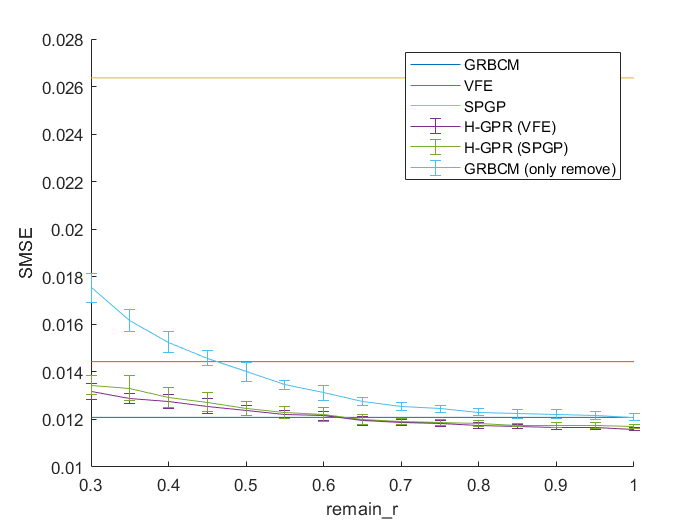

aamse = grbcm2_gr_smse(1:kti,:);
aamsll = grbcm2_gr_msll(1:kti,:);
mmse = mean(aamse);
mstd = std(aamse);
mmse_ro = mean(grbcm_gr_smse(1:kti,:));
mstd_ro = std(grbcm_gr_smse(1:kti,:));
mmse_sp = mean(grbcm2_spgp_gr_smse(1:kti,:));
mstd_sp = std(grbcm2_spgp_gr_smse(1:kti,:));

figure; hold on;
plot([min(grls), max(grls)], [grbcm0_smse,grbcm0_smse]);
plot([min(grls), max(grls)], [vfeSMSE_bl,vfeSMSE_bl]);
plot([min(grls), max(grls)], [spgpSMSE_bl,spgpSMSE_bl]);
errorbar(grls, mmse, mstd);
errorbar(grls, mmse_sp, mstd_sp);
errorbar(grls, mmse_ro, mstd_ro);
legend('GRBCM', 'VFE', 'SPGP', 'H-GPR (VFE)', 'H-GPR (SPGP)', 'GRBCM (only remove)');
xlabel('remain\_r'); ylabel('SMSE');

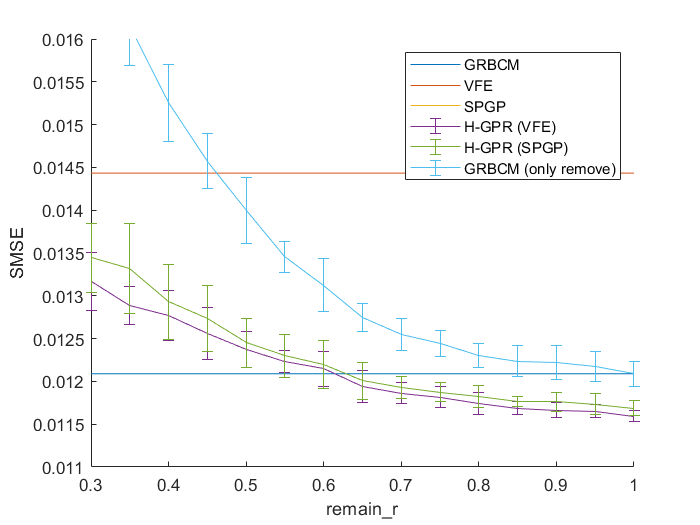

aamse = grbcm2_gr_smse(1:kti,:);
aamsll = grbcm2_gr_msll(1:kti,:);
mmse = mean(aamse);
mstd = std(aamse);
mmse_ro = mean(grbcm_gr_smse(1:kti,:));
mstd_ro = std(grbcm_gr_smse(1:kti,:));
mmse_sp = mean(grbcm2_spgp_gr_smse(1:kti,:));
mstd_sp = std(grbcm2_spgp_gr_smse(1:kti,:));

figure; hold on;
plot([min(grls), max(grls)], [grbcm0_smse,grbcm0_smse]);
plot([min(grls), max(grls)], [vfeSMSE_bl,vfeSMSE_bl]);
plot([min(grls), max(grls)], [spgpSMSE_bl,spgpSMSE_bl]);
errorbar(grls, mmse, mstd);
errorbar(grls, mmse_sp, mstd_sp);
errorbar(grls, mmse_ro, mstd_ro);
legend('GRBCM', 'VFE', 'SPGP', 'H-GPR (VFE)', 'H-GPR (SPGP)', 'GRBCM (only remove)');
xlabel('remain\_r'); ylabel('SMSE');
ylim([0.011, 0.016]);

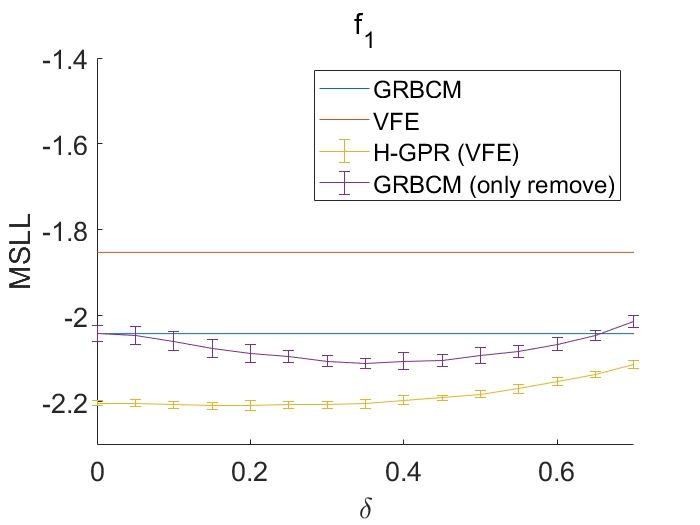

mmsll = mean(aamsll);
mstd = std(aamsll);
mmsll_ro = mean(grbcm_gr_msll(1:kti,:));
mstd_ro = std(grbcm_gr_msll(1:kti,:));
mmsll_sp = mean(grbcm2_spgp_gr_msll(1:kti,:));
mstd_sp = std(grbcm2_spgp_gr_msll(1:kti,:));
figure; hold on;
plot([0, 0.7], [grbcm0_msll,grbcm0_msll]);
plot([0, 0.7], [vfeMSLL_bl,vfeMSLL_bl]);
%plot([min(grls), max(grls)], [spgpMSLL_bl,spgpMSLL_bl]);
errorbar(0:0.05:0.7, flip(mmsll), flip(mstd));
%errorbar(grls, mmsll_sp, mstd_sp);
errorbar(0:0.05:0.7, flip(mmsll_ro), flip(mstd_ro));
legend('GRBCM', 'VFE', 'H-GPR (VFE)', 'GRBCM (only remove)');
%legend('GRBCM', 'VFE', 'SPGP', 'H-GPR (VFE)', 'H-GPR (SPGP)', 'GRBCM (only remove)');
xlabel('\delta'); ylabel('MSLL');
ylim([-2.3, -1.4]);
xlim([0, 0.7]);
title('f_1')
set(gca,'fontsize', 16);

fprintf('Best SMSE (GRBCM+VFE, dcs %d, ecs %d): %6.8f\n', dcs, ecs, min(mmse));

Best SMSE (GRBCM+VFE, dcs 150, ecs 150): 0.01159231


fprintf('Best MSLL (GRBCM+VFE, dcs %d, ecs %d): %6.8f\n', dcs, ecs, min(mmsll));

Best MSLL (GRBCM+VFE, dcs 150, ecs 150): -2.20840538



fprintf('Best SMSE (GRBCM+SPGP, dcs %d, ecs %d): %6.8f\n', dcs, ecs, min(mmse_sp));

Best SMSE (GRBCM+SPGP, dcs 150, ecs 150): 0.01168647


fprintf('Best MSLL (GRBCM+SPGP, dcs %d, ecs %d): %6.8f\n', dcs, ecs, min(mmsll_sp));

Best MSLL (GRBCM+SPGP, dcs 150, ecs 150): -2.18825519
